Constantes

mu0 = 4*pi*10e-7;
%I = 100;
a = 0.03;
A = pi*a^2;

a_ring = 0.1;
momento = 2000; %Investigar 
m = 0.03; %Investigar 
R = 1;
dt = 0.01;
g = -9.81;

Inicializar matrices

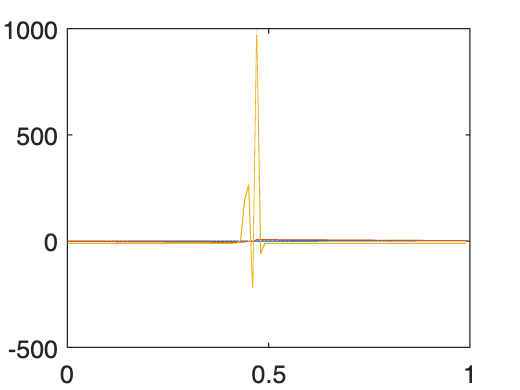

n = 100;

N = 2;

z = zeros(1,n);

B = zeros(1,n);

flujo = zeros(1,n);

fem = zeros(1,n);

I_inducida = zeros(1,n);

B_inducida = zeros(1,n);

Fz = zeros(1,n);

acel = zeros(1,n);

vz = zeros(1,n);

t = zeros(1,n);

zz = zeros(1,n);

vzz = zeros(1,n);

for i = 1:n
    if i == 1
        z(1) = 1;
        B(1) = mu0*momento/( 2*pi*(a^2 + z(1)^2)^(3/2) );
        flujo(1) = B(1)*A;
        fem(1) = 0;
        I_inducida(1) = 0;
        B_inducida(1) = 0;
        Fz(1) = 0;
        acel(1) = g;
        vz(1) = 0;
        t(1) = 0;
        zz(1) = z(1);
        vzz(1) =0;
    else
        B(i) = mu0*momento/( 2*pi*(a^2 + z(i-1)^2)^(3/2) );
        flujo(i) = B(i)*A;
        fem(i) = -(flujo(i)-flujo(i-1))/dt;
        I_inducida(i) = fem(i)/R;
        B_inducida(i) = mu0*I_inducida(i)*a_ring^2/( 2*(a_ring^2 + z(i-1)^2)^(3/2) );
        momentoSol = I_inducida(i)*a_ring^2*pi;
        %Fz(i) = (mu0/4*pi)*momento*momentoSol/z(i-1)^2;
        Fz(i) = B_inducida(i)*momento/z(i-1);
        acel(i) = (-Fz(i) + m*g)/m;
        vz(i) = vz(i-1)+acel(i)*dt;
        z(i) = z(i-1) + (vz(i)*dt) + 0.5*acel(i)*dt^2;
        t(i) = t(i-1) + dt;
        vzz(i) = vzz(i-1)+g*dt;
        zz(i) = zz(i-1)+vzz(i)*dt + 0.5*g*dt^2;
    end
end

plot (t,z)
hold on
plot(t,vz)
plot(t, acel)